Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment - 1**

% Setting the value of heaviside(0) to 1
sympref('HeavisideAtOrigin', 1);

**Q1:**

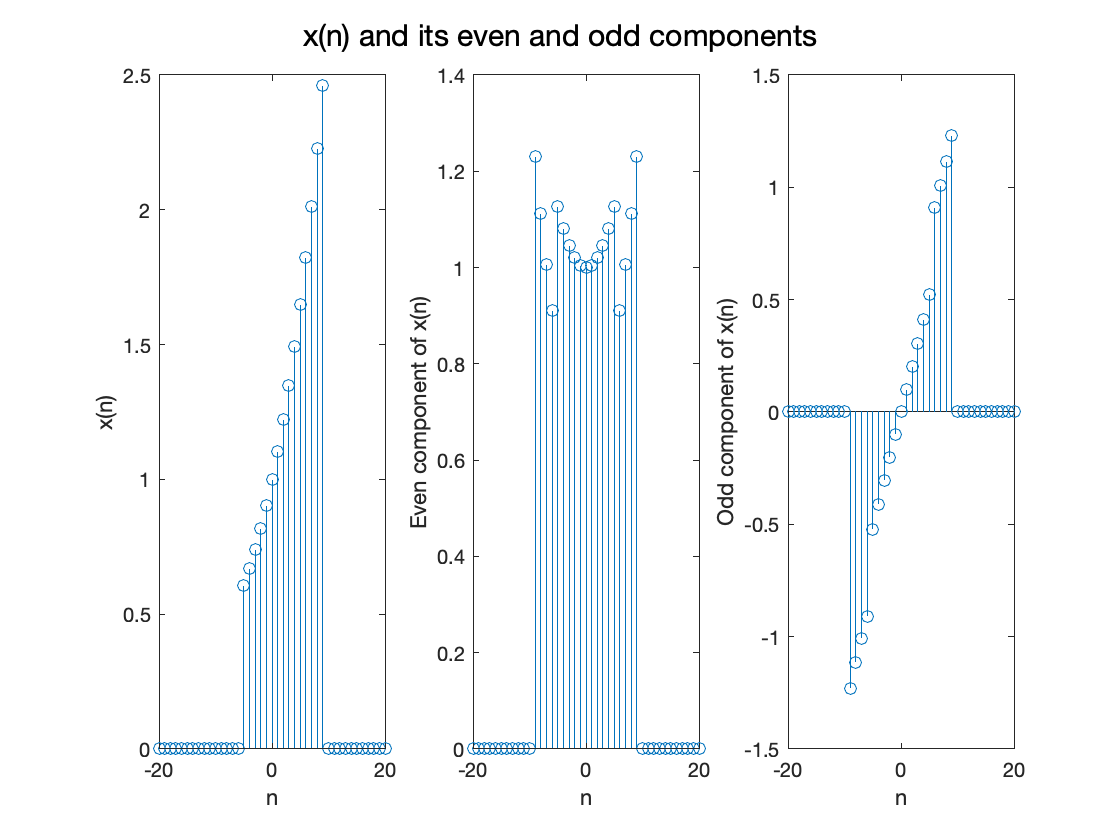

n = (-20:1:20);
x = @(n) exp(0.1 * n) .* (heaviside(n + 5) - heaviside(n - 10));

% The function evenodd is defined at the end of this file
[evenComponent, oddComponent] = evenodd(x);

subplot(1, 3, 1);
stem(n, x(n));
xlabel('n'); ylabel('x(n)');

subplot(1, 3, 2);
stem(n, evenComponent(n));
xlabel('n'); ylabel('Even component of x(n)');

subplot(1, 3, 3);
stem(n, oddComponent(n));
xlabel('n'); ylabel('Odd component of x(n)');

sgtitle('x(n) and its even and odd components');

**Q2:**

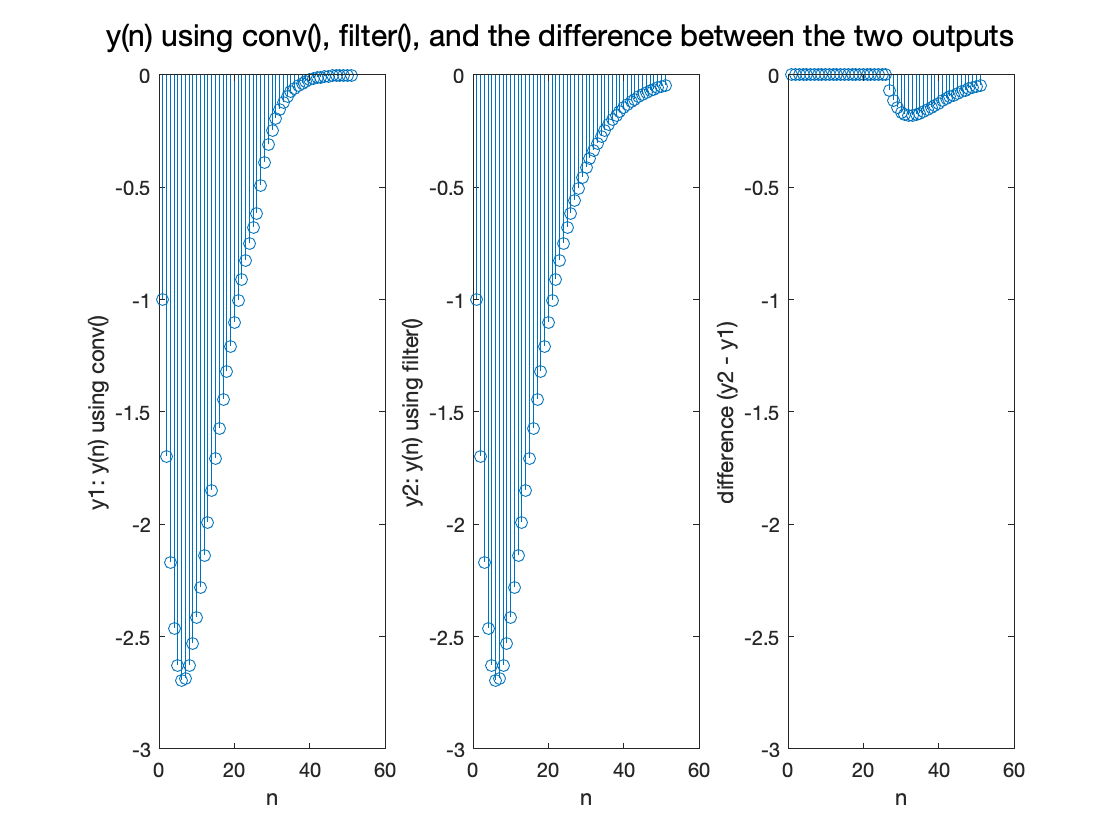

% The length of vector 'n' is 70
n = 0:69;

x = @(n) (0.8 .^ n) .* heaviside(n);
h = @(n) (-0.9 .^ n) .* heaviside(n);

xn = x(n);
hn = h(n);

truncated_xn = xn(1:26);
truncated_hn = hn(1:26);

y1 = conv(truncated_xn, truncated_hn);
y2 = filter(hn, 1, xn(1:51));
difference = y2 - y1;

subplot(1, 3, 1);
stem(y1);
xlabel("n"); ylabel("y1: y(n) using conv()");

subplot(1, 3, 2);
stem(y2);
xlabel("n"); ylabel("y2: y(n) using filter()");

subplot(1, 3, 3);
stem(difference);
xlabel("n"); ylabel("difference (y2 - y1)"); axis([0, 60, -3, 0]);

sgtitle("y(n) using conv(), filter(), and the difference between the two outputs");

**Q3:**

% Part (a)
xn = [1, 2, 3, 4, 5];
hn = [6, 7, 8, 9];
yn = conv(hn, xn);

% Part (b)
x = xn';
y = yn';
H = calculateToeplitz(hn, xn);

% Checking whether y = Hx
q3b_verified = isequal(H*x, y);
display(q3b_verified);

q3b_verified = logical
   1


Since q3b_verified = 1, we have verified that y = Hx holds for the resulting value of H.

display(H);

H =      6     0     0     0     0
     7     6     0     0     0
     8     7     6     0     0
     9     8     7     6     0
     0     9     8     7     6
     0     0     9     8     7
     0     0     0     9     8
     0     0     0     0     9


3c) A Toeplitz matrix or diagonal-constant matrix, is a matrix in which each descending diagonal from left to right is constant. The convolution operation can be constructed as a matrix multiplication, where one of the inputs is converted into a toeplitz matrix. A linear shift invariant operator is equivalent to a matrix multiplication with a toeplitz matrix.

3d) The first row of the toeplitz matrix contains all zeroes, except for the first element, whose value is equal to the first value of the impulse response vector h(n). Each column of the toeplitz matrix has a length equal to the length of y(n), which is the result of convolution of x(n) and h(n). The first column of the toeplitz matrix contains all the elements of h(n) followed by zeroes in the remaining indices.

**Q4:**

[y2, H2] = conv_tp(hn, xn);

% Verifying that y2 and H2 were calculated correctly
q4_y_verified = isequal(y, y2);
q4_H_verified = isequal(H, H2);

display([q4_y_verified, q4_H_verified]);

  1×2 logical array

   1   1



display(y2);

y2 =      6
    19
    40
    70
   100
    94
    76
    45


display(H2);

H2 =      6     0     0     0     0
     7     6     0     0     0
     8     7     6     0     0
     9     8     7     6     0
     0     9     8     7     6
     0     0     9     8     7
     0     0     0     9     8
     0     0     0     0     9


From the above results, we have verified that we get the same values of y and H as in Q3.

function [evenComponent, oddComponent] = evenodd(inputFunction)
    % Creating a function handle that points to the even component of the input function
    evenComponent = @(n) (inputFunction(n) + inputFunction(-n))/2;
    
    % Creating a function handle that points to the odd component of the input function
    oddComponent = @(n) (inputFunction(n) - inputFunction(-n))/2;
end

% The below function expects h and x to be row vectors
function H = calculateToeplitz(h, x)
    len_h = length(h);
    len_x = length(x);
    prefixSuffixHelper = [zeros(1, len_x - 1) flip(h) zeros(1, len_x - 1)];
    
    H = zeros(len_h + len_x - 1, len_x);
    for i = 1:(len_h + len_x - 1)
        startIndex = length(prefixSuffixHelper) - (len_x - 1) - (i - 1);
        endIndex = length(prefixSuffixHelper) - (i - 1);
        H(i, :) = prefixSuffixHelper(startIndex:endIndex);
    end
end

% The below function expects h and x to be row vectors
function [y, H] = conv_tp(h, x)
    len_x = length(x);
    firstRow = [h(1) zeros(1, len_x - 1)];
    firstColumn = [h' zeros(len_x - 1, 1)];
    
    H = toeplitz(firstColumn, firstRow);
    y = H * x';
end